# Tercer Examen Parcial

# Primavera 2024

Sube tu archivo resultado a Canvas $\to$ Examen Parcial 3 antes de las 11:30 horas. 

**Aseguráte que tus resultados se despliegan en el archivo que subas.**

Al final del script debes incluir las funciones usadas para resolver las preguntas.

Cada pregunta vale 5 puntos.

Si no usas la función indicada se restan 2 puntos en la respuesta. 

Los exámenes son trabajos individuales. Está estrictamente prohibido dar o recibir ayuda de cualquier persona. 

**Recuerda salvar frecuentemente tu archivo.**

Puede ser conveniente limpiar periódicamente el espacio de trabajo (comando clear).

En el caso extremo de gráficas que aparecen mal, puedes salir y volver a entrar a la sesión.

## Pregunta 1.

Para simular la dinámica de una poblacion se utiliza el modelo logistico:


$$p^{\prime } =k_{\textrm{gm}} \left(1-\frac{p}{p_{\max } }\right)p$$


donde *p *es la población, $k_{\textrm{gm}}$ es la tasa máxima de crecimiento en condiciones ilimitadas y$p_{\max }$ es la capacidad de carga. El modelo logístico combina dos procesos ecológicos: 

- reproducción ($p^{\prime } =k_{\textrm{gm}} p$)  

- competencia ($p^{\prime } ={-k}_{\textrm{gm}} \frac{p^2 }{p_{\max } }$).

Simula la población mundial (resolviendo la ecuación diferencial, usando Euler) entre 1950 y 2024, sabiendo que en 1950 había 2555 millones de personas. Para la simulación utiliza los siguientes valores de parametros: $k_{\textrm{gm}} =0\ldotp 026/\textrm{año}$ y $p_{\max } =11000$ millones de personas.

disp('Problema 1')

Problema 1


kgm = 0.026;            % por año
pMax = 11000;           % millones
p0 = 2555;
f = @(t, p) kgm*(1-(p/pMax))*p;
tspan = [1950 2024];

[t, y] = odeEuler(f, p0, tspan, 1);

Grafica de manera adecuada, con etiquetas en los ejes y un grid, la población mundial en función del tiempo.

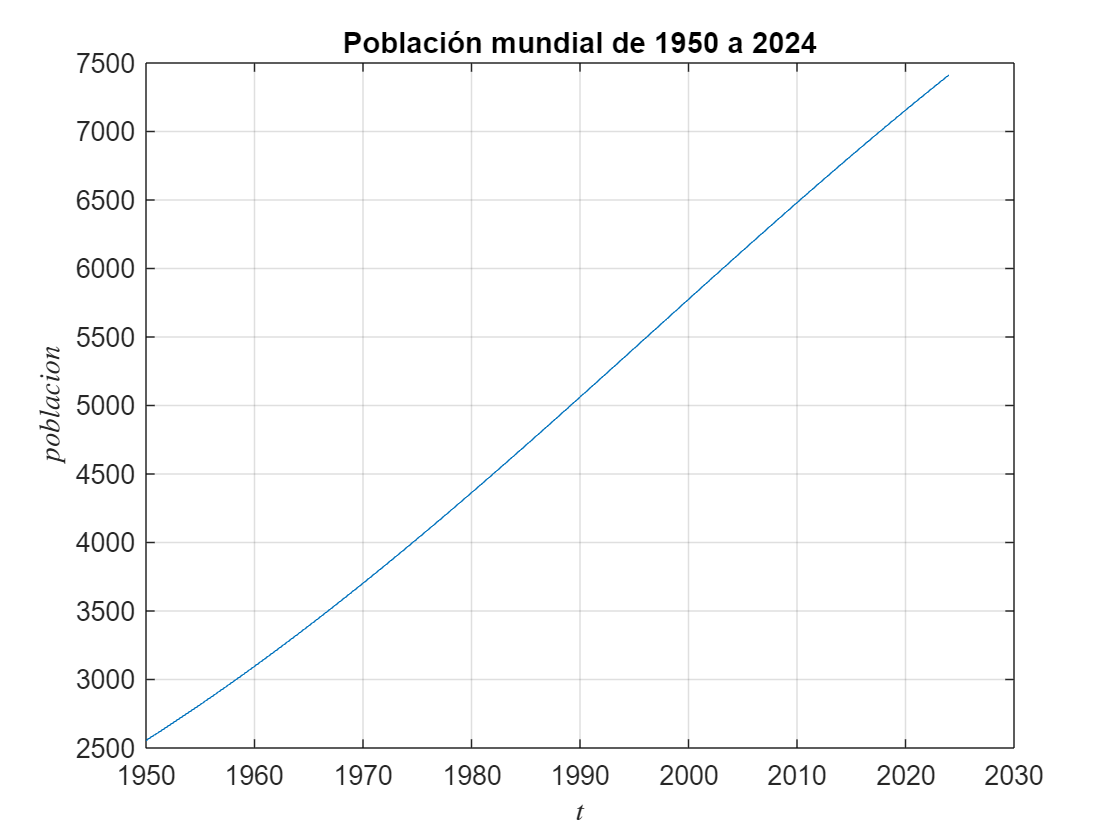

plot(t, y)
title('Población mundial de 1950 a 2024')
xlabel('$t$','interpreter','latex')
ylabel('$poblacion$','interpreter','latex')
grid on

¿Cuántos millones de personas hay en 2024 según el modelo?

fprintf('En 2024 hay %f millones de personas', y(end))

En 2024 hay 7412.518442 millones de personas

## Pregunta 2.

Considera el siguiente sistema de dos ecuaciones diferenciales ordinarias con valores iniciales:


$$y^{\prime } =y+z$$
                    
$$y\left(0\right)=0\ldotp 1$$



$$z^{\prime } =-y+z$$
                   
$$z\left(0\right)=0\ldotp 2$$


Resuelve numéricamente, usando RK4, el sistema en el intervalo [0 10].

disp('Problema 2')

Problema 2


f = @(t, yz) [yz(1) + yz(2); -yz(1) + yz(2)];
yz0 = [0.1; 0.2];
tspan = [0 10];
[t, yz] = odeRK4(f, yz0, tspan, 0.1);

Grafica de manera adecuada, usando una etiqueta y una leyenda, los valores de$y$ y de $z$.

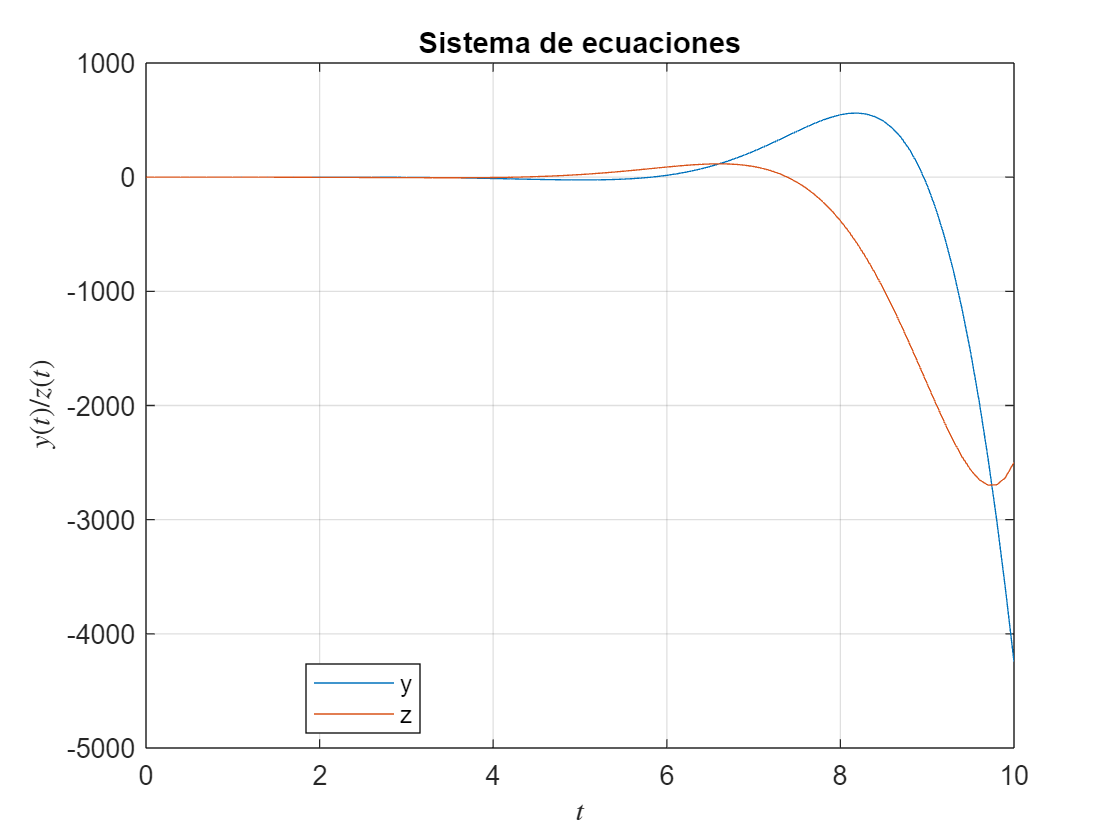

plot(t, yz(1, :))
hold on
plot(t, yz(2, :))
title('Sistema de ecuaciones')
xlabel('$t$','Interpreter','latex')
ylabel('$y(t)/z(t)$','Interpreter','latex')
legend('y', 'z', 'location', 'best')
grid on
hold off

Muestra que los eigenvalores de la matriz M asociada al sistema ${\left(\textrm{yz}\right)}^{\prime } =M*\textrm{yz}$ son complejos conjugados.

M = [1 1; -1 1];
eigM = eig(M);
disp(eigM)

   1.0000 + 1.0000i
   1.0000 - 1.0000i



La parte real de los eigenvalores corresponde al exponente de un función exponencial y la parte imaginaria a la frecuencia de un seno y un coseno.

## Pregunta 3.

The Lotka-Volterra equations, also known as the predator-prey equations, are a pair of first-order, nonlinear, differential equations frequently used to describe the dynamics of biological systems in which two species interact, one as a predator and the other as prey. 

The populations change through time according to the pair of equations ($p_1$ prey, $p_2$ predator):

                   
$$\frac {\mathrm{d}p_1} {dt} = \alpha*p_1 - \beta * p_1* p_2
\\ \frac {\mathrm{d}p_2} {dt} = \delta * p_1 * p_2  -\gamma * p_2$$


where t is time, $\alpha$ is the natural growth rate of preys (rabbits), $\gamma$ is the natural death rate of predators (foxes), $\beta$ is the death rate of preys per one unit of the predator population, and $\delta$ is the growth rate of predators per one unit of the prey population.

For general parameters $\alpha$, $\beta$, $\gamma$, $\delta$, there is no closed-form solution to this problem. The only way to solve this problem is using a numerical solver.

Usando los siguientes valores $\alpha =0\ldotp 4$, $\beta =0\ldotp 018$, $\delta =0\ldotp 023$, $\gamma =0\ldotp 8$,

y los valores iniciales $p_1 \left(0\right)=30$ y $p_2 \left(0\right)=4$.

Simula la población de presas y depredadores en el intervalo [0 30], usando el método ABM4 y h=0.1.

disp('Problema 3')

Problema 3


alfa = 0.4;
beta = 0.018;
delta = 0.023;
gama = 0.8;
h = 0.1;
tspan = [0 30];
p0 = [30; 4];
f = @(t, p) [alfa.*p(1) - beta.*p(1).*p(2); 
    delta.*p(1).*p(2) - gama.*p(2)];

[t, y] = ABM4(f, p0, tspan, h);

Grafica de manera adecuada los valores de $p_1$ y $p_2$.

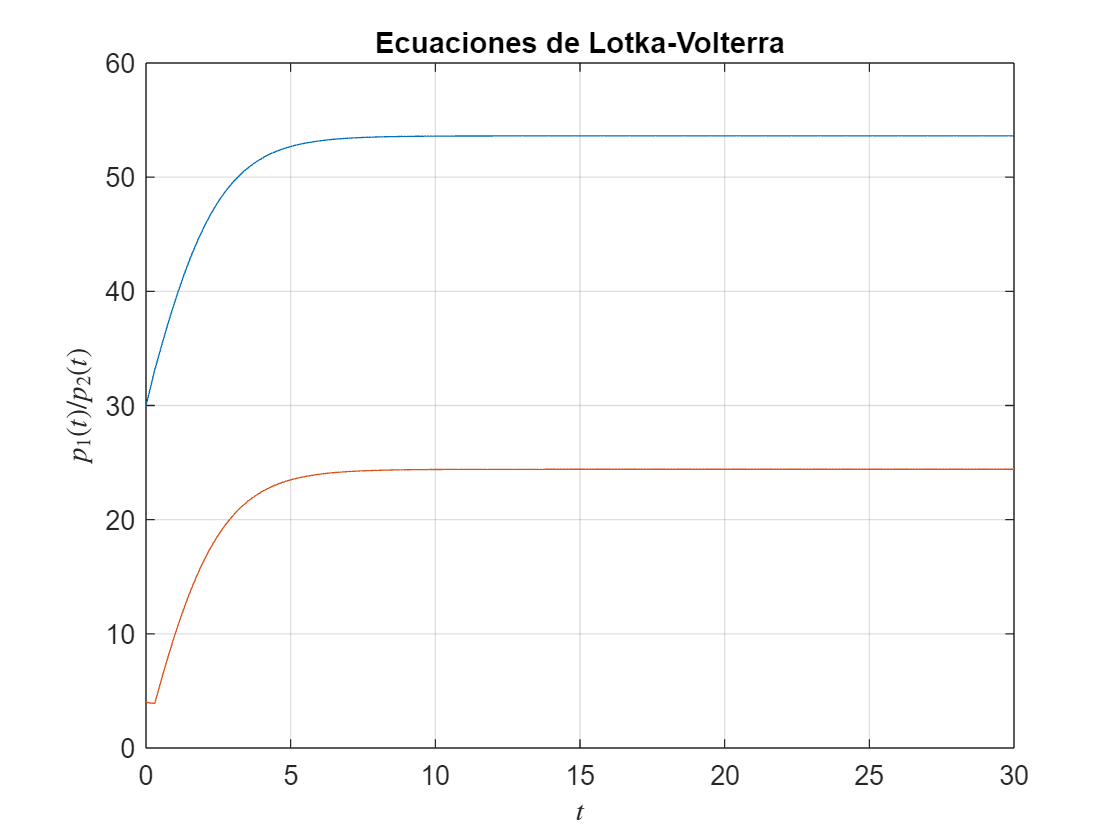

plot(t, y(1, :))
hold on
plot(t, y(2, :))
grid on
title('Ecuaciones de Lotka-Volterra')
xlabel('$t$','interpreter','latex')
ylabel('$p_1(t)/p_2(t)$','interpreter','latex')
hold off

Grafica de manera adecuada el número de presas contra el número de depredadores ($p_1$ vs $p_2$).

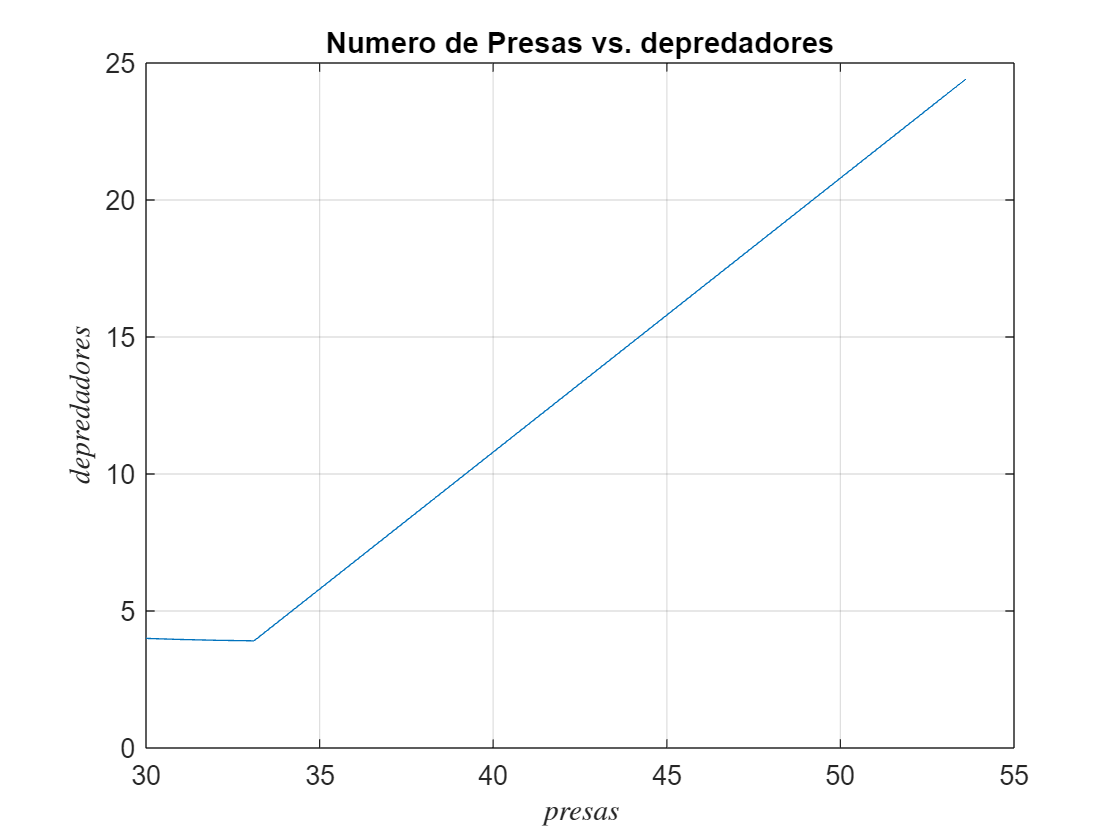

plot(y(1, :), y(2, :))
title('Numero de Presas vs. depredadores')
grid on
xlabel('$presas$','interpreter','latex')
ylabel('$depredadores$','interpreter','latex')

## Pregunta 4.

Resuelve de manera numérica, con RK4 y h=0.1, la ecuación diferencial de tercer orden


$$\frac{{\mathrm{d}}^3 }{\mathrm{d}t^3 }x+x=0$$


con las condiciones iniciales $x^{\prime \prime } \left(0\right)=0,{\;x}^{\prime } \left(0\right)=1,\;x\left(0\right)=0$,

en el intervalo [0 , 10].

Para  resolver la ecuación, introduce las variables


$$x^{\prime } =y$$



$$y^{\prime } =z$$



$$\textrm{xyz}=\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack$$


disp('Problema 4')

Problema 4


M = [0 1 0; 0 0 1; -1 0 0];
f = @(t, xyz) M*xyz;
xyz0 = [0; 1; 0];
tspan = [0 10];
h = 0.1;
[t, xyz] = odeRK4(f, xyz0, tspan, h);

Grafica, de manera adecuada, $x\left(t\right)$.

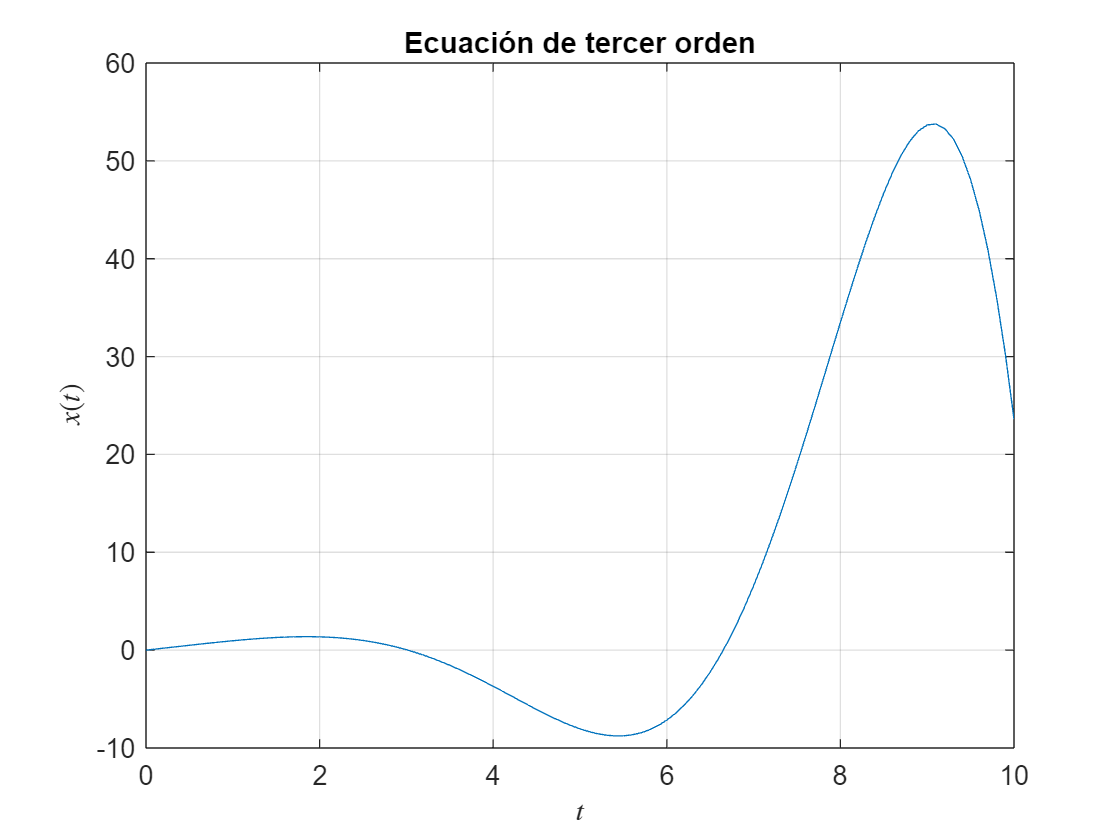

plot(t, xyz(1, :))
grid on
title('Ecuación de tercer orden')
xlabel('$t$','interpreter','latex')
ylabel('$x(t)$','interpreter','latex')

## Pregunta 5.

Resuelve, de manera numérica usando cualquier método, la siguiente ecuación diferencial de segundo orden:

$y^{\prime \prime } -y^{\prime } -2y=0$         $y\left(0\right)=0\ldotp 1$, $y^{\prime } \left(0\right)=0\ldotp 2$

en el intervalo [0 1].

Para  resolver la ecuación, introduce las variables:


$$y^{\prime } =z$$



$$\textrm{yz}=\left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack$$


disp('Problema 5')

Problema 5


f = @(t, yz) [yz(2); yz(2) + 2*yz(1)];
y0 = [0.1; 0.2];
tspan = [0 1];
h = 0.1;
[t, y] = odeRK4(f, y0, tspan, h);

Grafica de manera adecuada los valores de $y$.

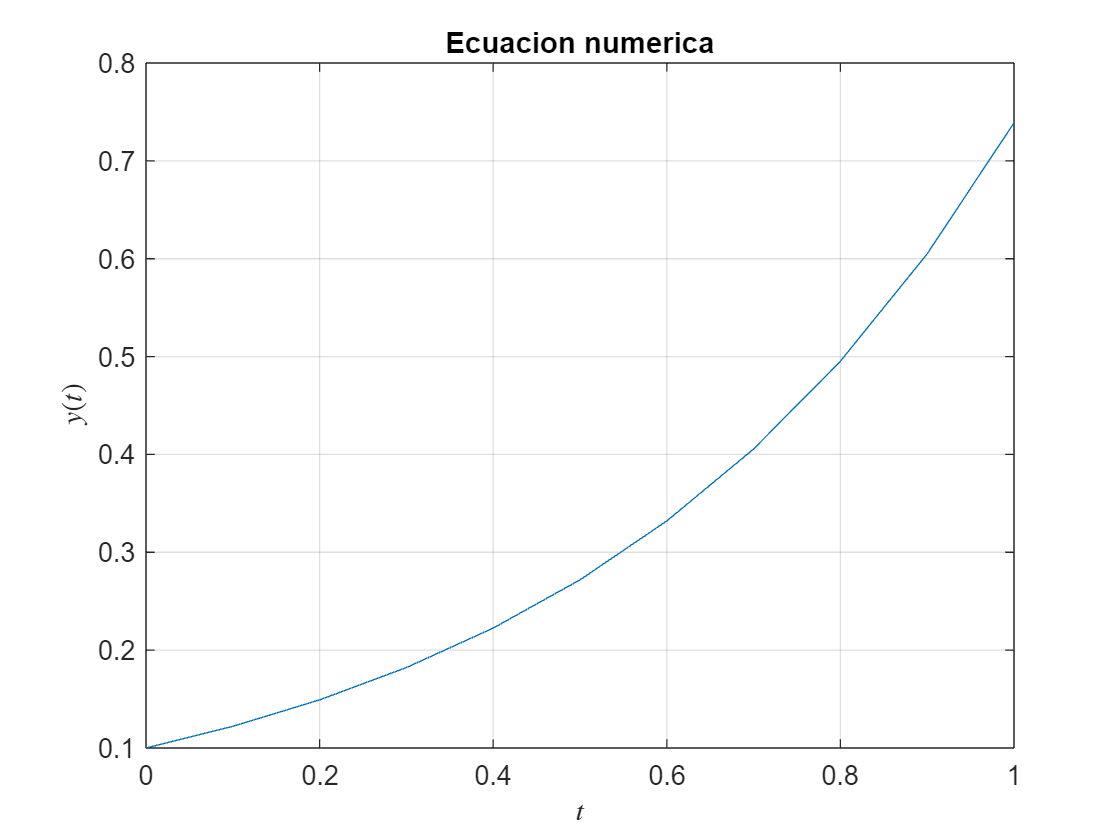

plot(t, y(1, :))
title('Ecuacion numerica')
xlabel('$t$','interpreter','latex')
ylabel('$y(t)$','interpreter','latex')
grid on

Encuentra los eigenvectores y eigenvalores de la matriz M asociada al sistema ${\left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack }^{\prime } =M*\left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack$

% [V, D]= eig(M)
M = [0 1; 1 2];
[V, eigM] = eig(M);
disp(V)

   -0.9239    0.3827
    0.3827    0.9239



disp(diag(eigM))

   -0.4142
    2.4142



Como los eigenvalores son reales distintos, la solución general $\textrm{yzG}$ del sistema de ecuaciones es:


$$\textrm{yzG}=\textrm{K1}*V\left(:,1\right)*\exp \left(D\left(1,1\right)*t\right)+\textrm{K2}*V\left(:,2\right)*\exp \left(D\left(2,2\right)*t\right)\;$$


Para encontrar la solución particular $\textrm{yzP}$ deseada usamos la condición inicial (t=0)


$$\mathrm{yz}\left(0\right)=\left\lbrack \begin{array}{c}
0\ldotp 1\\
0\ldotp 2
\end{array}\right\rbrack$$



$$\textrm{yzP}=\textrm{K1}*V\left(:,1\right)+\textrm{K2}*V\left(:,2\right)=V*\left\lbrack \begin{array}{c}
\textrm{K1}\\
\textrm{K2}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\ldotp 1\\
0\ldotp 2
\end{array}\right\rbrack$$


Resuelve este sistema de ecuaciones, usando \, para encontrar los valores de $\textrm{K1}$y $\textrm{K2}$.

yz0 = [0.1; 0.2];
k = V\yz0;

Calcula $\textrm{K1}*V\left(:,1\right)$ y $\textrm{K2}*V\left(:,2\right)$

k(1)*V(:, 1)

ans =     0.0146
   -0.0061


k(2)*V(:, 2)

ans =     0.0854
    0.2061


Observa que $y=0\ldotp 1*\exp \left(2*t\right)$.

Finalmente, resuelve de manera simbólica la ecuación diferencial.

syms y(t)
y0 = 0.1;
eqn = diff(y) == 0.1*exp(2*t);
cnd = y(0) == y0;
yP = dsolve(eqn, cnd)

$$yP = \frac{{\mathrm{e}}^{2\,t}}{20}+\frac{1}{20}$$

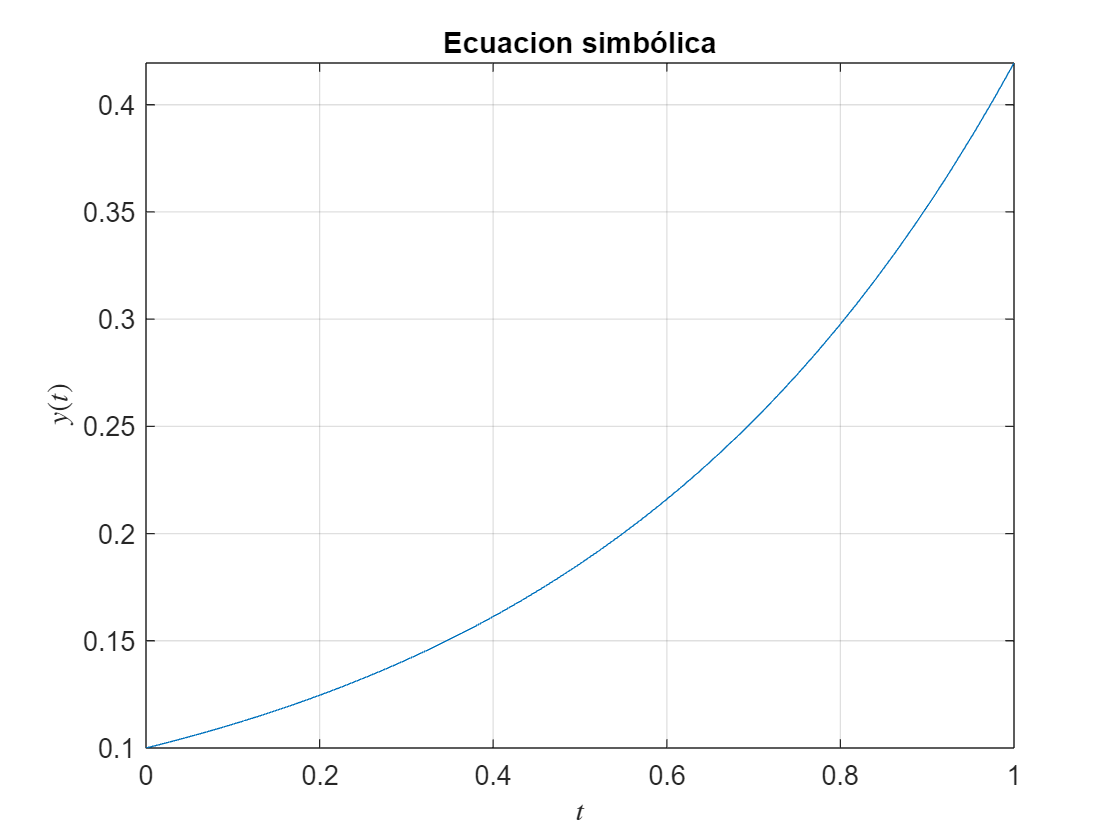

fplot(yP, tspan)
title('Ecuacion simbólica')
xlabel('$t$','interpreter','latex')
ylabel('$y(t)$','interpreter','latex')
grid on

## Funciones utilizadas

function [t, y] = odeEuler(f, y0, tspan, h)
    t0 = tspan(1);
    tn = tspan(2);
    
    t = t0:h:tn;
    n = length(t);
    y = zeros(length(y0), n);
    y(:, 1) = y0;
    for i = 1:n-1
        phi = f(t(i), y(:, i));
        y(:, i+1) = y(:, i) + phi*h;
    end
end

function [t, y] = odeRK4(f, y0, tspan, h)
    t = tspan(1):h:tspan(2);
    n = length(t);
    y = zeros(length(y0), n);

    y(:, 1) = y0;
    for i = 1:n-1
        ti = t(i);
        yi = y(:, i);
        k1 = f(ti, yi);
        k2 = f(ti + 1/2*h, yi + 1/2*k1*h);
        k3 = f(ti + 1/2*h, yi + 1/2*k2*h);
        k4 = f(ti + h, yi + k3*h);

        y(:, i+1) = yi + 1/6*(k1 + 2*k2 + 2*k3 + k4)*h;
    end
end

function [t, y] = ABM4(f, y0, tspan, h)
    t = tspan(1):h:tspan(2);
    n = length(t);
    m = length(y0);
    y = zeros(m, n);
    y(:, 1) = y0;
    
    [~, y(:, 1:4)] = odeRK4(f, y0, [t(1) t(4)], h);
    fv = bsxfun(f, t(1:4), y(:, 1:4));
    for i = 4:n-1
        yi = y(:, i);
        y(:, i+1) = yi + h/24*(55*fv(4) - 59*fv(3) + 37*fv(2) - 9*fv(1));
        fv(:, 1:3) = fv(:, 2:4);
        fv(:, 4) = f(t(i+1), y(:, i+1));
        
        y(:, i+1) = yi + h/24*(9*fv(4) + 19*fv(3) - 5*fv(2) + fv(1));
        fv(:, 4) = f(t(i+1), y(:, i+1));
    end
end